# FCDD_Train

#### **Fred liu 2023.07.17**

**update 2024.02.17**

2022b之後的版本更新了三種異常偵測的演算法，分別是：

**Fully convolitional data description(FCDD)**

**FastFlow**

**PatchCore**

詳細資訊可以在此連結中找到：[Getting Started with Anomaly Detection Using Deep Learning](https://www.mathworks.com/help/vision/ug/getting-started-with-anomaly-detection-using-deep-learning.html)

### Download DataSet VisA

使用Dataset :  [VisA Visual Inspection Dataset](https://github.com/amazon-science/spot-diff)

datadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\";

### 載入資料與資料分割(Load Data & Splits Dataset )

dsPCB = imageDatastore(datadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(dsPCB.Labels)

     Anomaly       100 
     Normal       1005 


分割成訓練、驗證，與測試資料集

[dsTrain,dsVal,dsTest] = splitAnomalyData(dsPCB,"Anomaly");

Splitting anomaly dataset
-------------------------
* Finalizing... Done.
* Number of files and proportions per class in all the datasets:

                      Input                  Train              Validation                Test        
               NumFiles     Ratio      NumFiles    Ratio    NumFiles     Ratio     NumFiles     Ratio 
               ____________________    _________________    ___________________    ___________________

    Anomaly       100      0.090498        0         0         34       0.25373       66       0.24627
    Normal       1005        0.9095      703         1        100       0.74627      202       0.75373



### 顯示資料庫影像

正常影像

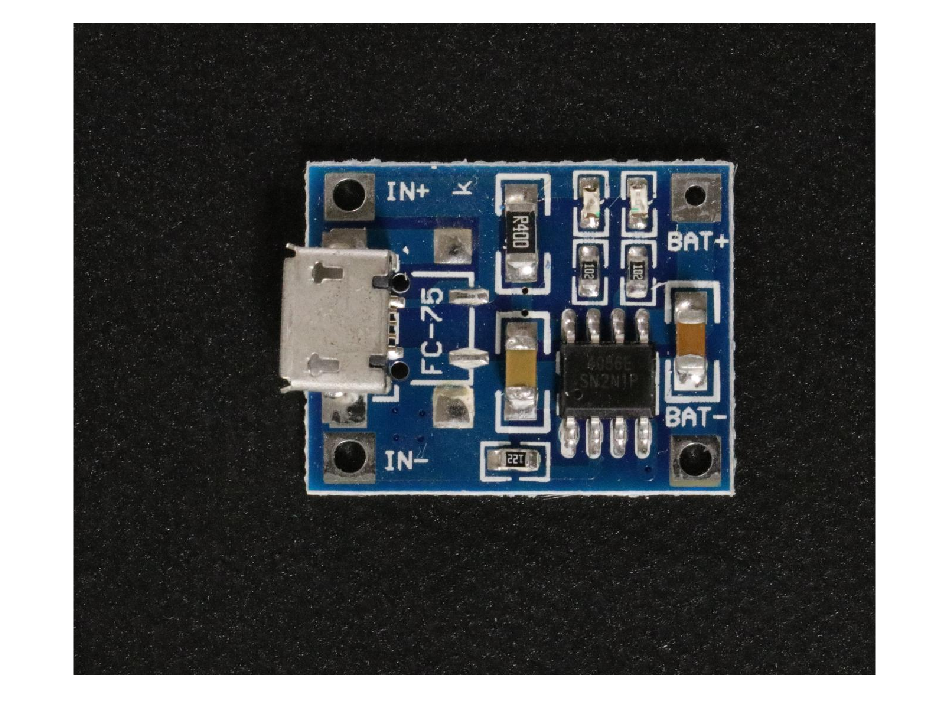

figure,imshow(preview(dsTrain))

異常影像

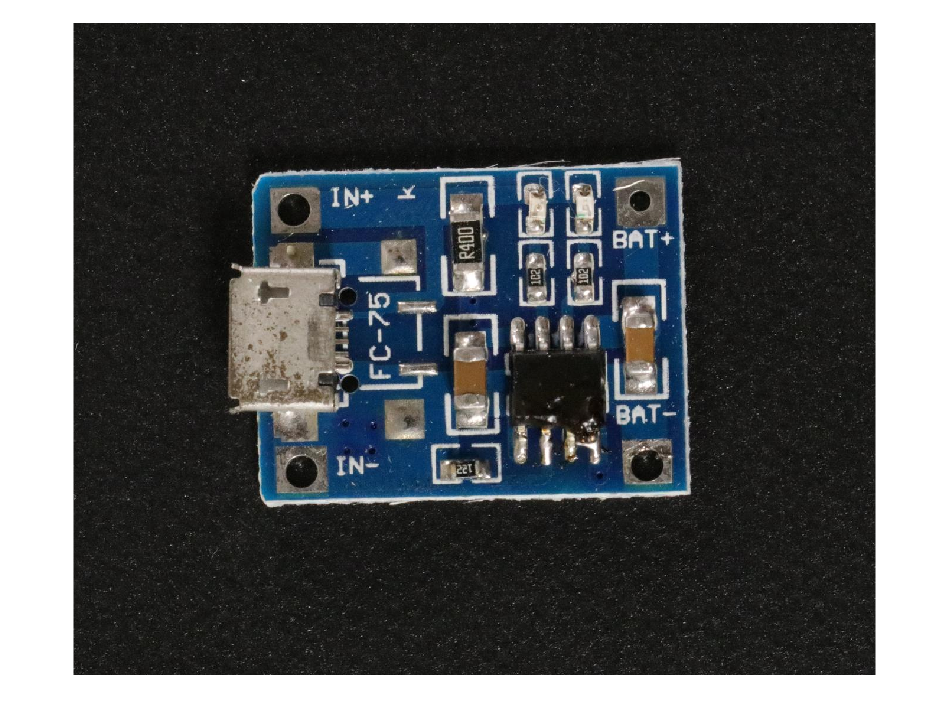

badImage = find(dsTest.Labels=="Anomaly",1);
imshow(read(subset(dsTest,badImage)))

### 資料前處理

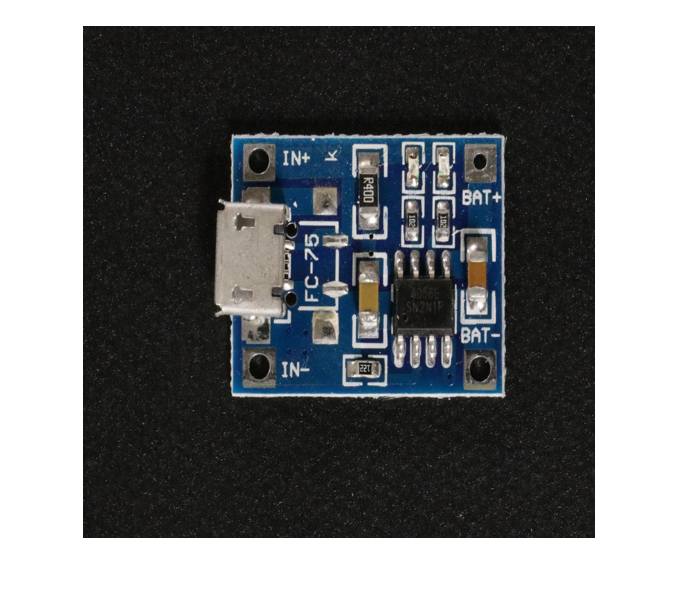

size(preview(dsTrain));
resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
dsTrain = transform(dsTrain,resizeFcn);
dsVal = transform(dsVal,resizeFcn);
dsTest = transform(dsTest,resizeFcn);

imshow(preview(dsTrain))

### 建立模型(FCDD)

fcdd = fcddAnomalyDetector(pretrainedEncoderNetwork("resnet50",3));

### 切割驗證資料集

dsValGoodIdx = dsVal.UnderlyingDatastores{1}.Labels == "Normal";
dsValGood = subset(dsVal,dsValGoodIdx);
dsValBad = subset(dsVal,~dsValGoodIdx);

### 訓練與參數設定

設定相關訓練的參數，訓練時用FCDDAnomalyDetector為例：

另外兩個detector如下

[`detector = trainFastFlowAnomalyDetector(normalData,detectorIn,options)`](https://127.0.0.1:31515/static/help/vision/ref/trainfastflowanomalydetector.html?snc=RQNRIH&searchsource=mw&container=jshelpbrowser#d124e290693)

[`detector = trainPatchCoreAnomalyDetector(normalData,detectorIn)`](https://127.0.0.1:31515/static/help/vision/ref/trainpatchcoreanomalydetector.html?snc=PF3D69&searchsource=mw&container=jshelpbrowser#d124e291486)

options = trainingOptions('adam',...
    Shuffle='every-epoch',...
    MaxEpochs=30,...
    ValidationData={dsValGood,dsValBad},...
    BatchNormalizationStatistics='moving', ...
    MiniBatchSize=128,...
    OutputNetwork='best-validation-loss');

normalIdx = dsTrain.UnderlyingDatastores{1}.Labels == "Normal";
normalDataTrain = subset(dsTrain,find(normalIdx));
badDataTrain = subset(dsTrain,find(~normalIdx));

detector = trainFCDDAnomalyDetector(normalDataTrain,dsValBad,fcdd,options);

Computing Input Normalization Statistics.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingFcddLoss    ValidationFcddLoss
    _____    _________    ___________    _________    ________________    __________________
      5         50         00:02:30        0.001           0.2971              0.27889      
     10         100        00:04:59        0.001          0.19326               0.1655      
     14         150        00:07:24        0.001          0.20302              0.17142      
     19         200        00:09:53        0.001           0.1093              0.12274      
     24         250        00:12:22        0.001          0.12309               0.1123      
     28         300        00:14:45        0.001          0.080374             0.089807     


### 測試影像

載入單張影像進行異常偵測測試

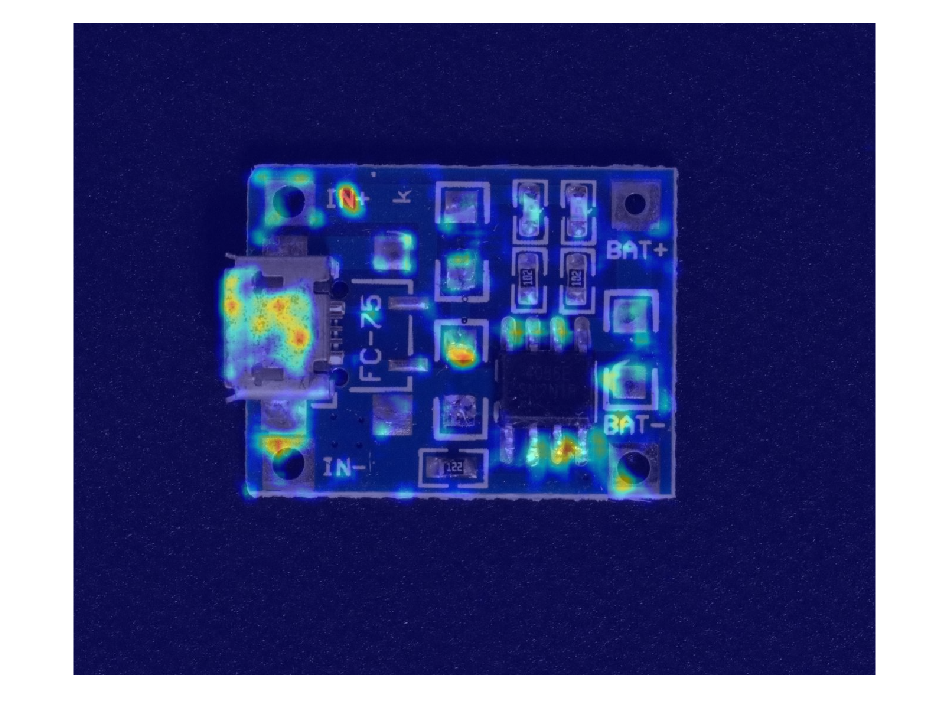

AnomalyImage = imread("D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\Anomaly\050.JPG");
displayRange = [0,162];
map2 = anomalyMap(detector,AnomalyImage);
%image2 = (anomalyMapOverlay(AnomalyImage,map2,MapRange=displayRange,Blend="equal"));
image2 = (anomalyMapOverlay(AnomalyImage,map2,Blend="equal"));
figure,imshow(image2)

## 資料庫檢測

Testdatadir = "D:\Fred\MATLAB_Project(myself)\AnomalyDetection\VisA_20220922\VisA_20220922\pcb4\Data\Images\";
TestdsPCB = imageDatastore(Testdatadir,IncludeSubfolders=true,LabelSource="foldernames");
summary(TestdsPCB.Labels)
resizeFcn = @(x) imresize(x,OutputSize=[512 512]);
TestdsPCB = transform(TestdsPCB,resizeFcn);
figure,imshow(preview(TestdsPCB))

gtLabels = TestdsPCB.UnderlyingDatastores{1,1}.Labels;
anomalyLabels = "Anomaly";
predScores = predict(detector_FastFlow,TestdsPCB);

View the anomaly detection results.

[T,roc] = anomalyThreshold(gtLabels,predScores,anomalyLabels)
